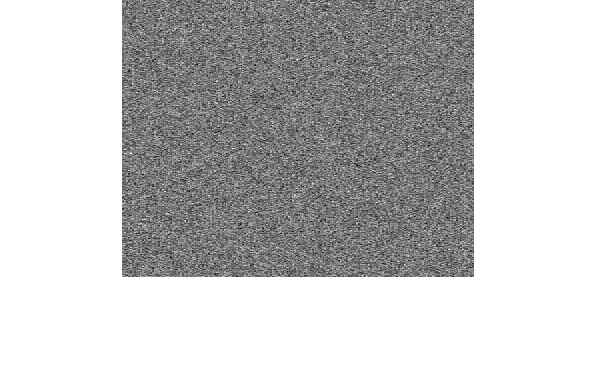

%Load variables
load random_img.mat
load foreman_cif.mat
rimg = rimg/255;
yseq = yseq/255;
imshow(rimg)

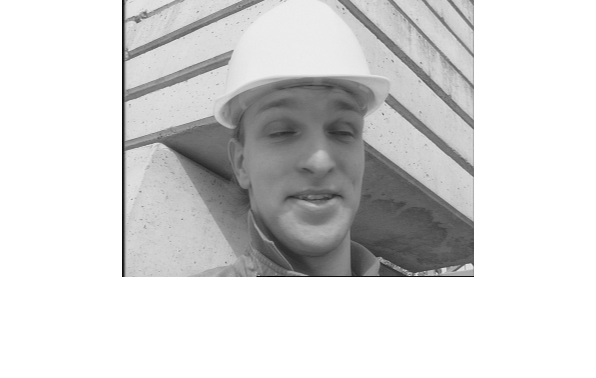

imshow(yseq)

%DCT type II and DST type I
rhos = [0.1,0.3,0.5,0.7,0.8,0.9,0.98];
U_DCT = dctmtx(8);
eta_DCT = zeros(1,7);
for i = 1:7
    rho = rhos(i);
    Cov = getCov(rho);
    eta_DCT(i) = computeDE(U_DCT*Cov*U_DCT.',Cov);
end

disp(eta_DCT);

    0.6981    0.7900    0.8650    0.9271    0.9539    0.9782    0.9958




U_DST = dstmtx();
U_DST = U_DST.';
eta_DST = zeros(1,7);
for i = 1:7
    rho = rhos(i);
    Cov = getCov(rho);
    eta_DST(i) = computeDE(U_DST*Cov*U_DST.',Cov);
end

disp(eta_DST);

    0.6981    0.7900    0.8650    0.9271    0.9539    0.9782    0.9958



%KLT
X = zeros(500,8);
for i = 1:250
    X(i,:) = rimg(i,55:62);
end
for i = 251:500
    X(i,:) = yseq(i-230,55:62);
end
temp = cov(X);
[U_KLT,~] = eig(temp);
U_KLT = U_KLT.';
for i = 1:7
    rho = rhos(i);
    Cov = getCov(rho);
    eta_KLT(i) = computeDE(U_KLT*Cov*U_KLT.',Cov);
end
disp(eta_KLT);

    0.1828    0.3818    0.5766    0.7588    0.8453    0.9268    0.9737



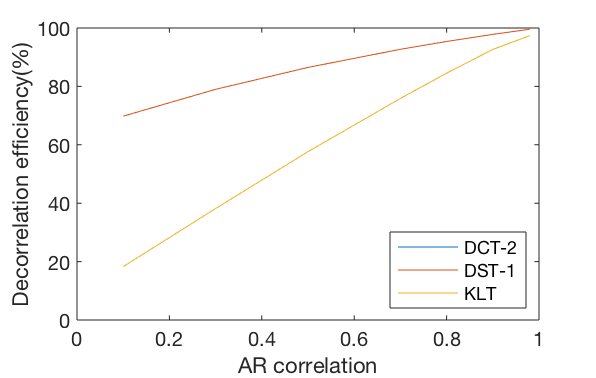

%Visualization
fig = figure(1);
plot(rhos,eta_DCT*100);
hold on;
plot(rhos,eta_DST*100);
hold on;
plot(rhos,eta_KLT*100);
xlabel("AR correlation");
ylabel("Decorrelation efficiency(%)");
legend('DCT-2','DST-1','KLT','Location','southeast');
saveas(fig,"Result.jpg");